# Experimental Design Matrix for Frontier Methods with Preprocessing

## *Chocó Map*

### 0. Preparing environment

#### 1. Clear command window, workspace variables, and close all figures. Turn off warnings.

clear; clc; close all;
warning('off', 'all');

#### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/';

#### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

Unrecognized function or variable 'ReadLayers'.

Defining Experimental Matrix

mapsAmount = 150;
nicheOccupations = [0.3, 0.6, 0.9];
samples = [20, 50, 100, 500];
correlationPercentages = [0.7, 0.8, 0.9];

warning("off", "all")
[matrixPreprocessing, matrixNoPreprocessing] = ExperimentalMatrixCode(Layers, mapsAmount,nicheOccupations,samples,correlationPercentages);

save('results.mat','matrixPreprocessing','matrixNoPreprocessing')

matrixNoPreprocessingL = matrixNoPreprocessing;
matrixPreprocessingL = matrixPreprocessing;

matrixPreprocessingFinal = NaN(48, length(nicheOccupations),length(samples),length(correlationPercentages),2);
matrixNoPreprocessingFinal = NaN(48, length(nicheOccupations),length(samples),2);
matrixPreprocessingFinal(1:20,:,:,:,:) = matrixPreprocessingL;
matrixPreprocessingFinal(21:48,:,:,:,:) = matrixPreprocessing(1:28,:,:,:,:);
matrixNoPreprocessingFinal(1:20,:,:,:) = matrixNoPreprocessingL;
matrixNoPreprocessingFinal(21:48,:,:,:) = matrixNoPreprocessing(1:28,:,:,:);


matrixPreprocessingFinal = matrixPreprocessing;
matrixNoPreprocessingFinal = matrixNoPreprocessing;

# Analyzing Results

## Frontier Depth with Preprocessing

matrixPFinal= NaN(length(nicheOccupations),length(samples),length(correlationPercentages),2);
valFinalMin = 1;
valFinalMax = 0;

for i=1:3
    for j=1:4
        for k =1:3
            matrixPFinal(i,j,k,1)=mean(matrixPreprocessingFinal(:,i,j,k,1));
            matrixPFinal(i,j,k,2)=mean(matrixPreprocessingFinal(:,i,j,k,2));
        end
        [valMin,idxMin]=min(matrixPFinal(i,j,:,2));
        if valFinalMin > valMin
            iFinalMin = i; jFinalMin = j; kFinalMin = idxMin; valFinalMin = valMin;
        end
        [valMax,idxMax]=max(matrixPFinal(i,j,:,2));
        if valFinalMax < valMax
            iFinalMax = i; jFinalMax = j; kFinalMax = idxMax; valFinalMax = valMax;
        end
    end
end


i: occupation, j: number of samples, k: correlation%

The experimental conditions that lead to the **worst **results are:

valFinalMin, iFinalMin, jFinalMin, kFinalMin

valFinalMin = 0.6503

iFinalMin = 3

jFinalMin = 1

kFinalMin = 1

The experimental conditions that lead to the **best **results are:

valFinalMax, iFinalMax, jFinalMax, kFinalMax

valFinalMax = 0.8349

iFinalMax = 1

jFinalMax = 4

kFinalMax = 2

### Visualizing Results

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.7

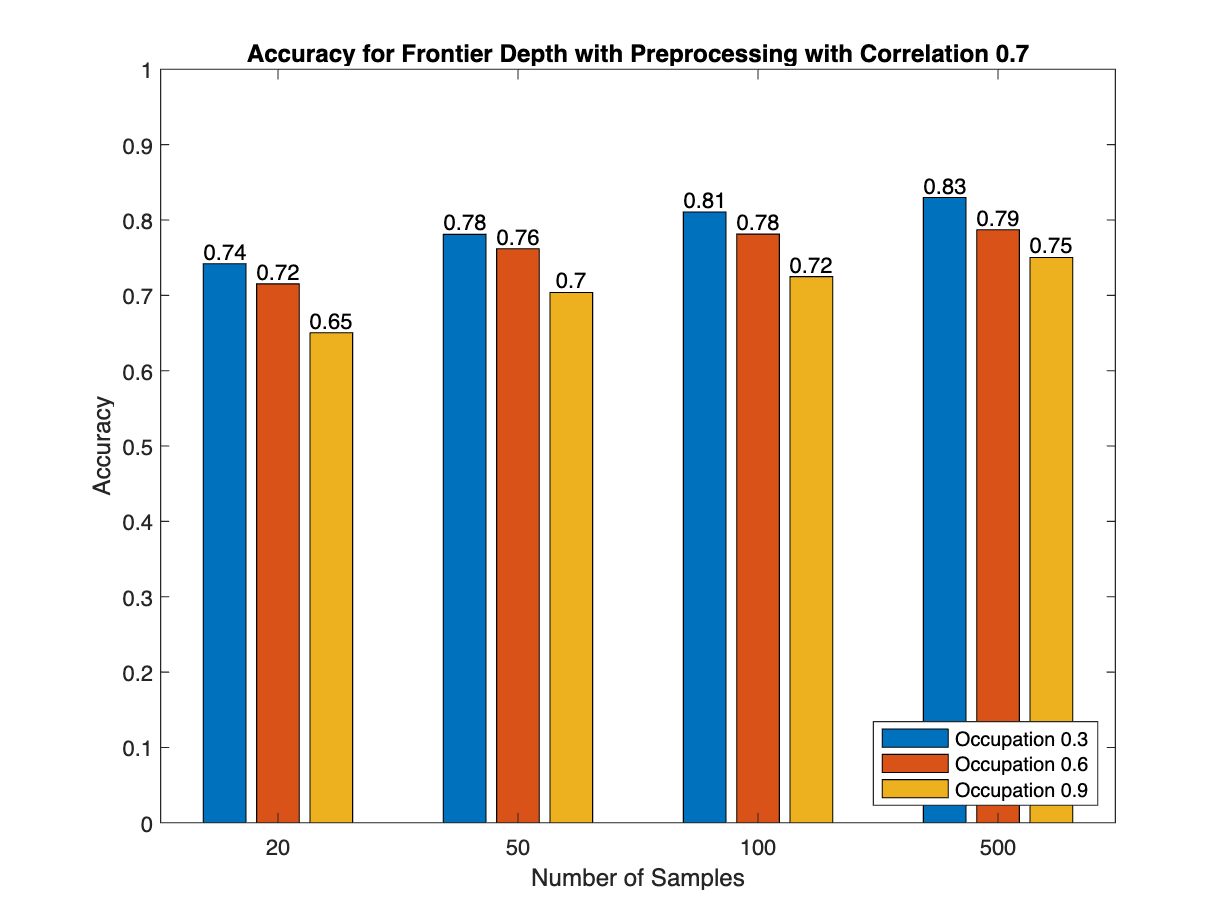

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,1,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.7")

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.8

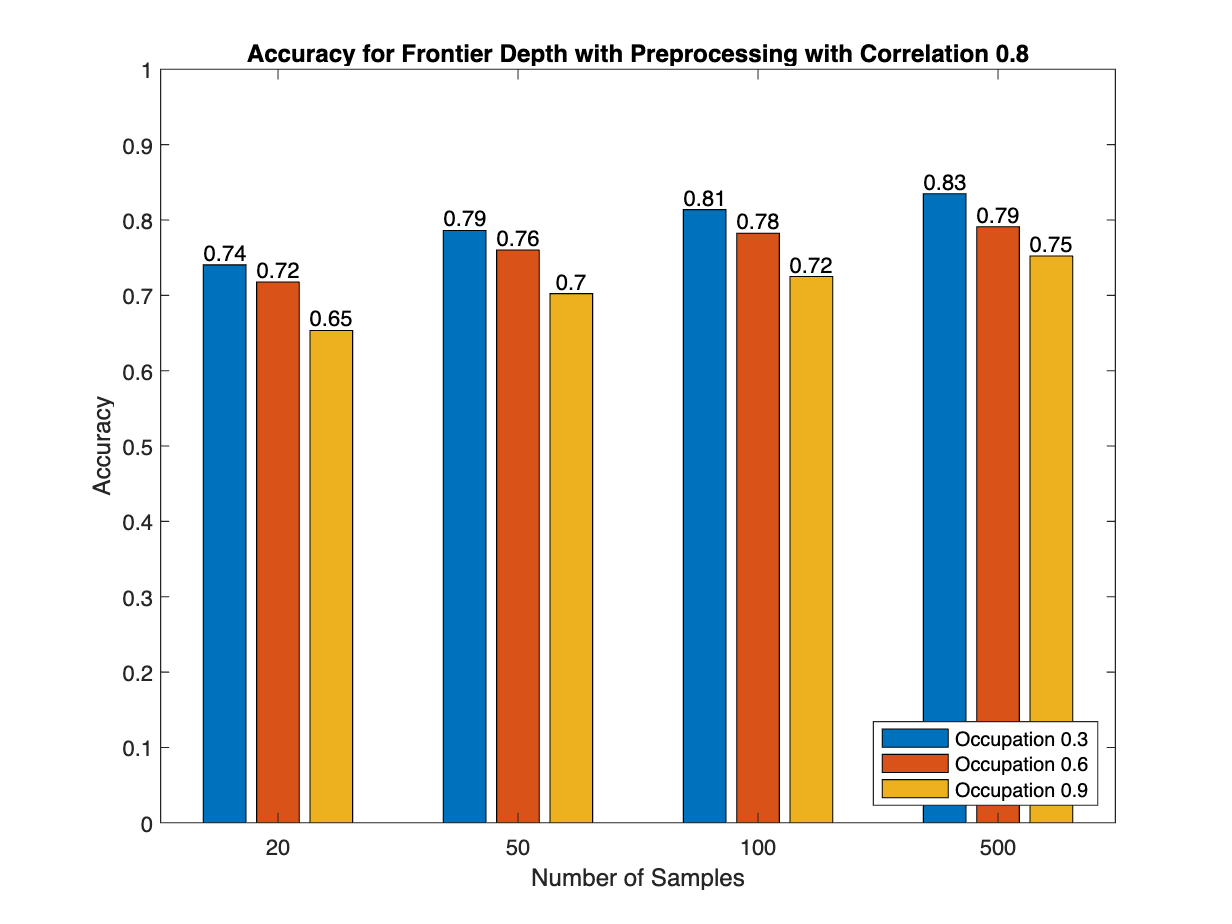

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,2,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.8")

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.7

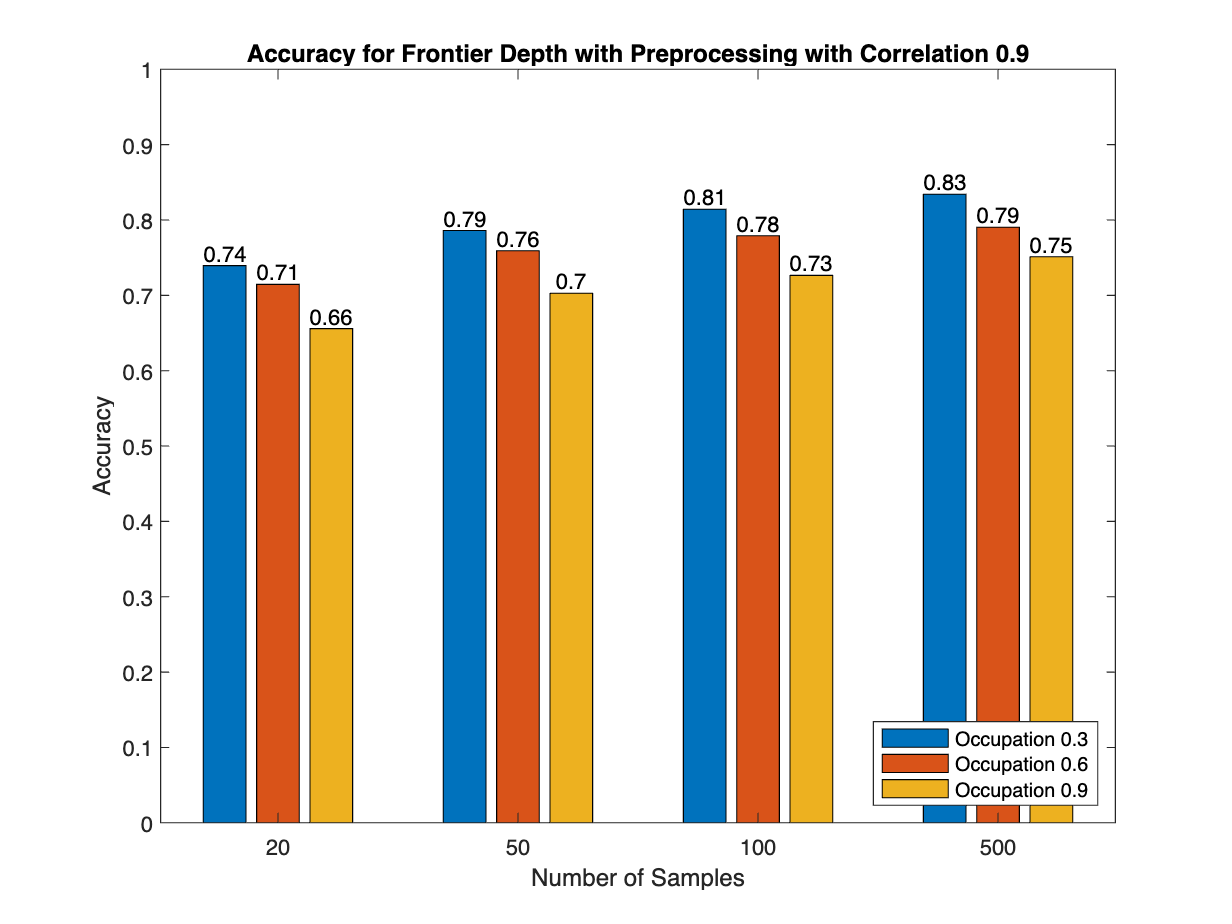

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,3,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.9")

# Analyzing Results

## Frontier Depth with Preprocessing

matrixNPFinal= NaN(length(nicheOccupations),length(samples),2);
valFinalMin = 1;
valFinalMax = 0;
for i=1:3
    for j=1:4
            matrixNPFinal(i,j,1)=mean(matrixNoPreprocessingFinal(:,i,j,1));
            matrixNPFinal(i,j,2)=mean(matrixNoPreprocessingFinal(:,i,j,2));
    end
    [valMin,idxMin]=min(matrixNPFinal(i,:,2));
    if valFinalMin > valMin
        iFinalMin = i; jFinalMin = idxMin; valFinalMin = valMin;
    end
    [valMax,idxMax]=max(matrixNPFinal(i,:,2));
    if valFinalMax < valMax
        iFinalMax = i; jFinalMax = idxMax; valFinalMax = valMax;
    end

end

i: occupation, j: number of samples

The experimental conditions that lead to the **worst **results are:

valFinalMin, iFinalMin, jFinalMin

valFinalMin = 0.6641

iFinalMin = 3

jFinalMin = 1

The experimental conditions that lead to the **best **results are:

valFinalMax, iFinalMax, jFinalMax

valFinalMax = 0.8359

iFinalMax = 1

jFinalMax = 4

### Visualizing Results

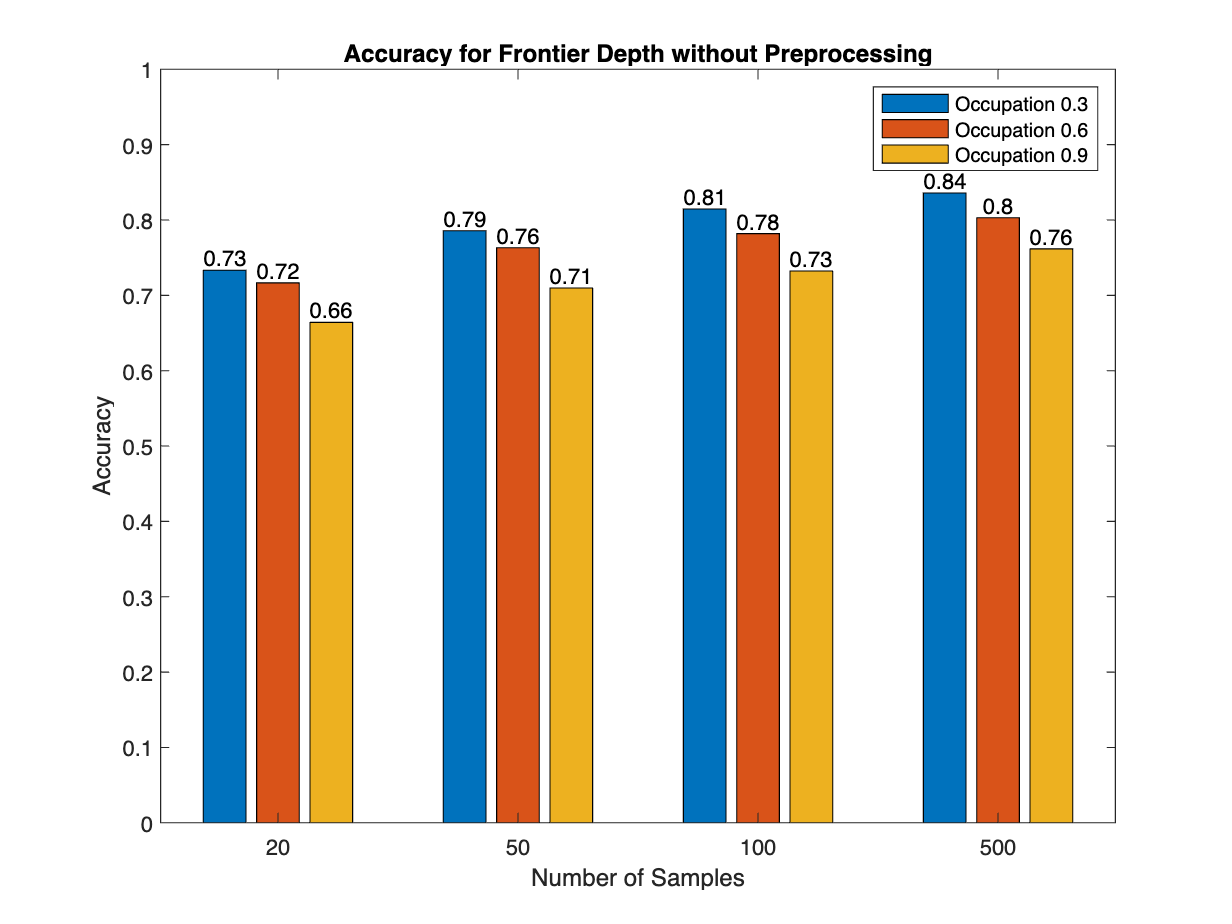

a = NaN(3,4);
a(:,:)= matrixNPFinal(:,:,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"})
title("Accuracy for Frontier Depth without Preprocessing")

## Visualizing Results Using a Boxplot

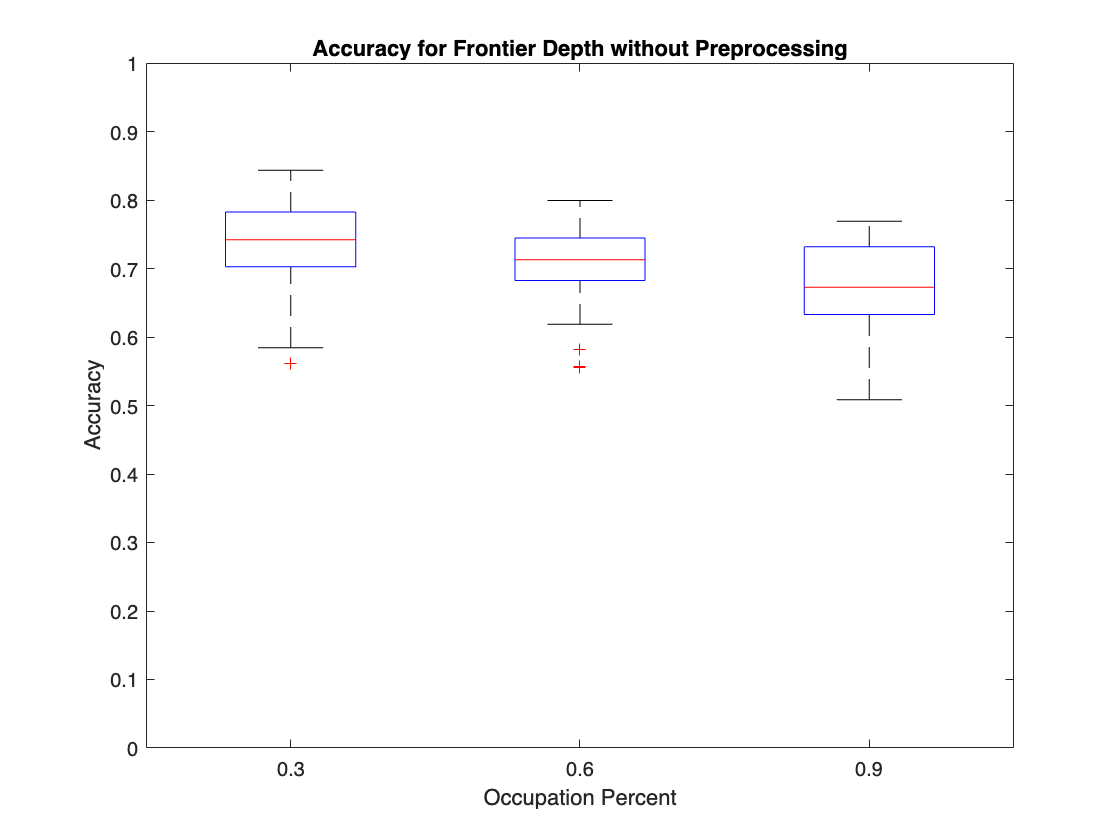

boxplot(matrixNoPreprocessingFinal(:,:,1,2))
xlabel("Number of Samples")
xticklabels({"0.3","0.6","0.9"})
ylim([0 1])
ylabel("Accuracy")
xlabel({"Occupation Percent"})
title("Accuracy for Frontier Depth without Preprocessing")

# Experimental Design Matrix for Frontier Methods with Preprocessing

## *Chocó Map*

### 0. Preparing environment

#### 1. Clear command window, workspace variables, and close all figures. Turn off warnings.

clear; clc; close all;
warning('off', 'all');

#### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/';

#### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 2.416712 seconds.


warning("off", "all")
mapsAmount = 500;
[bestMap, averageMap, medianMap, worstMap, metricAlllMaps] = results(Layers,mapsAmount)

map = 1

map = 2

map = 3

map = 4

map = 5

map = 6

map = 7

map = 8

map = 9

map = 10

map = 11

map = 12

map = 13

map = 14

map = 15

map = 16

map = 17

map = 18

map = 19

map = 20

map = 21

map = 22

map = 23

map = 24

map = 25

map = 26

map = 27

map = 28

map = 29

map = 30

map = 31

map = 32

map = 33

map = 34

map = 35

map = 36

map = 37

map = 38

map = 39

map = 40

map = 41

map = 42

map = 43

map = 44

map = 45

map = 46

map = 47

map = 48

map = 49

map = 50

map = 51

map = 52

map = 53

map = 54

map = 55

map = 56

map = 57

map = 58

map = 59

map = 60

map = 61

map = 62

map = 63

map = 64

map = 65

map = 66

map = 67

map = 68

map = 69

map = 70

map = 71

map = 72

map = 73

map = 74

map = 75

map = 76

map = 77

map = 78

map = 79

map = 80

map = 81

map = 82

map = 83

map = 84

map = 85

map = 86

map = 87

map = 88

map = 89

map = 90

map = 91

map = 92

map = 93

map = 94

map = 95

map = 96

map = 97

map = 98

map = 99

map = 100

map = 101

map = 102

map = 103

map = 104

map = 105

map = 106

map = 107

map = 108

map = 109

map = 110

map = 111

map = 112

map = 113

map = 114

map = 115

map = 116

map = 117

map = 118

map = 119

map = 120

map = 121

map = 122

map = 123

map = 124

map = 125

map = 126

map = 127

map = 128

map = 129

map = 130

map = 131

map = 132

map = 133

map = 134

map = 135

map = 136

map = 137

map = 138

map = 139

map = 140

map = 141

map = 142

map = 143

map = 144

map = 145

map = 146

map = 147

map = 148

map = 149

map = 150

map = 151

map = 152

map = 153

map = 154

map = 155

map = 156

map = 157

map = 158

map = 159

map = 160

map = 161

map = 162

map = 163

map = 164

map = 165

map = 166

map = 167

map = 168

map = 169

map = 170

map = 171

map = 172

map = 173

map = 174

map = 175

map = 176

map = 177

map = 178

map = 179

map = 180

map = 181

map = 182

map = 183

map = 184

map = 185

map = 186

map = 187

map = 188

map = 189

map = 190

map = 191

map = 192

map = 193

map = 194

map = 195

map = 196

map = 197

map = 198

map = 199

map = 200

map = 201

map = 202

map = 203

map = 204

map = 205

map = 206

map = 207

map = 208

map = 209

map = 210

map = 211

map = 212

map = 213

map = 214

map = 215

map = 216

map = 217

map = 218

map = 219

map = 220

map = 221

map = 222

map = 223

map = 224

map = 225

map = 226

map = 227

map = 228

map = 229

map = 230

map = 231

map = 232

map = 233

map = 234

map = 235

map = 236

map = 237

map = 238

map = 239

map = 240

map = 241

map = 242

map = 243

map = 244

map = 245

map = 246

map = 247

map = 248

map = 249

map = 250

map = 251

map = 252

map = 253

map = 254

map = 255

map = 256

map = 257

map = 258

map = 259

map = 260

map = 261

map = 262

map = 263

map = 264

map = 265

map = 266

map = 267

map = 268

map = 269

map = 270

map = 271

map = 272

map = 273

map = 274

map = 275

map = 276

map = 277

map = 278

map = 279

map = 280

map = 281

map = 282

map = 283

map = 284

map = 285

map = 286

map = 287

map = 288

map = 289

map = 290

map = 291

map = 292

map = 293

map = 294

map = 295

map = 296

map = 297

map = 298

map = 299

map = 300

map = 301

map = 302

map = 303

map = 304

map = 305

map = 306

map = 307

map = 308

map = 309

map = 310

map = 311

map = 312

map = 313

map = 314

map = 315

map = 316

map = 317

map = 318

map = 319

map = 320

map = 321

map = 322

map = 323

map = 324

map = 325

map = 326

map = 327

map = 328

map = 329

map = 330

map = 331

map = 332

map = 333

map = 334

map = 335

map = 336

map = 337

map = 338

map = 339

map = 340

map = 341

map = 342

map = 343

map = 344

map = 345

map = 346

map = 347

map = 348

map = 349

map = 350

map = 351

map = 352

map = 353

map = 354

map = 355

map = 356

map = 357

map = 358

map = 359

map = 360

map = 361

map = 362

map = 363

map = 364

map = 365

map = 366

map = 367

map = 368

map = 369

map = 370

map = 371

map = 372

map = 373

map = 374

map = 375

map = 376

map = 377

map = 378

map = 379

map = 380

map = 381

map = 382

map = 383

map = 384

map = 385

map = 386

map = 387

map = 388

map = 389

map = 390

map = 391

map = 392

map = 393

map = 394

map = 395

map = 396

map = 397

map = 398

map = 399

map = 400

map = 401

map = 402

map = 403

map = 404

map = 405

map = 406

map = 407

map = 408

map = 409

map = 410

map = 411

map = 412

map = 413

map = 414

map = 415

map = 416

map = 417

map = 418

map = 419

map = 420

map = 421

map = 422

map = 423

map = 424

map = 425

map = 426

map = 427

map = 428

map = 429

map = 430

map = 431

map = 432

map = 433

map = 434

map = 435

map = 436

map = 437

map = 438

map = 439

map = 440

map = 441

map = 442

map = 443

map = 444

map = 445

map = 446

map = 447

map = 448

map = 449

map = 450

map = 451

map = 452

map = 453

map = 454

map = 455

map = 456

map = 457

map = 458

map = 459

map = 460

map = 461

map = 462

map = 463

map = 464

map = 465

map = 466

map = 467

map = 468

map = 469

map = 470

map = 471

map = 472

map = 473

map = 474

map = 475

map = 476

map = 477

map = 478

map = 479

map = 480

map = 481

map = 482

map = 483

map = 484

map = 485

map = 486

map = 487

map = 488

map = 489

map = 490

map = 491

map = 492

map = 493

map = 494

map = 495

map = 496

map = 497

map = 498

map = 499

map = 500

bestMap = 5×2 cell array
    {[     0.9221]}    {[     0.6410]}
    {  1×1  struct}    {  1×1  struct}
    {496×22 table }    {496×22 table }
    {  1×1  struct}    {  1×1  struct}
    {  1×1  struct}    {  1×1  struct}


averageMap = 5×1 cell array
    {[    0.7565]}
    { 1×1  struct}
    {50×22 table }
    { 1×1  struct}
    { 1×1  struct}


medianMap = 5×1 cell array
    {[    0.7538]}
    { 1×1  struct}
    {50×22 table }
    { 1×1  struct}
    { 1×1  struct}


worstMap = 5×2 cell array
    {[    0.8456]}    {[    0.3680]}
    { 1×1  struct}    { 1×1  struct}
    {20×22 table }    {20×22 table }
    { 1×1  struct}    { 1×1  struct}
    { 1×1  struct}    { 1×1  struct}


metricAlllMaps =     0.7608
    0.7710
    0.8221
    0.7753
    0.7612
    0.8080
    0.6156
    0.8260
    0.7445
    0.8312


save('best_worst_maps.mat','Layers','averageMap','medianMap','bestMap','worstMap','metricAlllMaps','mapsAmount')




map = worstMap;
filename = 'Worst_Performance_Best_Case.csv';

NAME = 'Worst_Performance_Best_Case_SP'+strings(length(map{3,1}.LONG),1);
LONG = map{3,1}.LONG; LAT = map{3,1}.LAT;
T = table(NAME, LONG, LAT)

T = 20×3 table
                  NAME                   LONG       LAT  
    ________________________________    _______    ______

    "Worst_Performance_Best_Case_SP"    -76.879    1.1042
    "Worst_Performance_Best_Case_SP"    -76.571    2.3375
    "Worst_Performance_Best_Case_SP"    -76.104    3.0375
    "Worst_Performance_Best_Case_SP"    -75.987    3.4042
    "Worst_Performance_Best_Case_SP"    -75.921    3.7958
    "Worst_Performance_Best_Case_SP"    -75.704    4.8708
    "Worst_Performance_Best_Case_SP"    -75.604    6.0375
    "Worst_Performance_Best_Case_SP"    -75.537    5.8375
    "Worst_Performance_Best_Case_SP"    -75.437    1.6958
    "Worst_Performance_Best_Case_SP"    -75.429    1.7875
    "Worst_Performance_Best_Case_SP"    -75.112    6.5875
    "Worst_Performance_Best_Case_SP"    -74.946    6.0625
    "Worst_Performance_Best_Case_SP"    -74.871    6.0292
    "Worst_P

writetable(T, filename, 'Delimiter', ',');